# HW 11

Practice

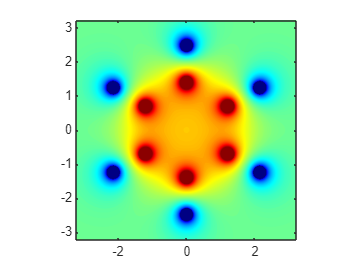

clear all
% Constants
eps0 = 8.85e-12;
k = 1 / (4 * pi * eps0);
R = 0.2;

% Read data from file
import = readtable('benzene.dat');
data = table2array(import(:, 2:5));

% Grid
minCoord = min([min(data(:,1)),min(data(:,2)),min(data(:,3))]);
maxCoord = max([max(data(:,1)),max(data(:,2)),max(data(:,3))]);
dist = maxCoord - minCoord;
step = dist/250;

[xg, yg] = meshgrid(minCoord*1.3:step:maxCoord*1.3);
Vtot = 0;

% Potencial calculation
for i = 1:length(data)
    x = data(i,1);
    y = data(i,2);
    q = -data(i,4);

    xi = xg - x;
    yi = yg - y;
    r = sqrt(xi.^2 + yi.^2);

    Vcur = q * k ./ r;
    Vtot = Vtot + Vcur;
end

for i = 1:length(data)
    xi = xg - data(i,1);
    yi = yg - data(i,2);
    r = sqrt(xi.^2 + yi.^2);
    
    Vm = -k * data(i,4) / R;
    Vtot(r < R) = Vm;
end

% 2D plot
figure;
contourf(xg,yg,Vtot,200,'LineStyle','none');
colormap(jet);
ax=gca;
axis(ax,'equal');

Homework - 3D

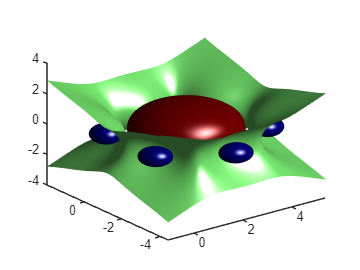

% Adaptation of the grid
[xg,yg,zg] = meshgrid(minCoord*1.3:step:maxCoord*1.3);

% Potencial calculation
Vtot = 0;
for i = 1:length(data)
    xi = xg - data(i,1);
    yi = yg - data(i,2);
    zi = zg - data(i,3);
    q = -1.6*10^(-19)*data(i,4);
    r = sqrt(xi.^2 + yi.^2 +zi.^2);

    Vcur = q * k ./r;
    Vtot = Vtot + Vcur;
end
for i = 1:length(data)
    xi = xg - data(i,1);
    yi = yg - data(i,2);
    zi = zg - data(i,3);
    r = sqrt(xi.^2 + yi.^2 +zi.^2);

    Vm = -k * data(i,4) / R;
    Vtot(r < R) = Vm;
end
% 3D plot
figure;
isosurface(xi,yi,zi,Vtot,0)
colormap(jet)
hold on
isosurface(xi,yi,zi,Vtot,1.0e-10)
isosurface(xi,yi,zi,Vtot,-1.0e-10)
hold off